# **Validation of resonant frequency equation**

**2023-06-12 ~**

**Vibration and Acoustic Transducers Laboratory**

**Pohang University of Science and Technology**

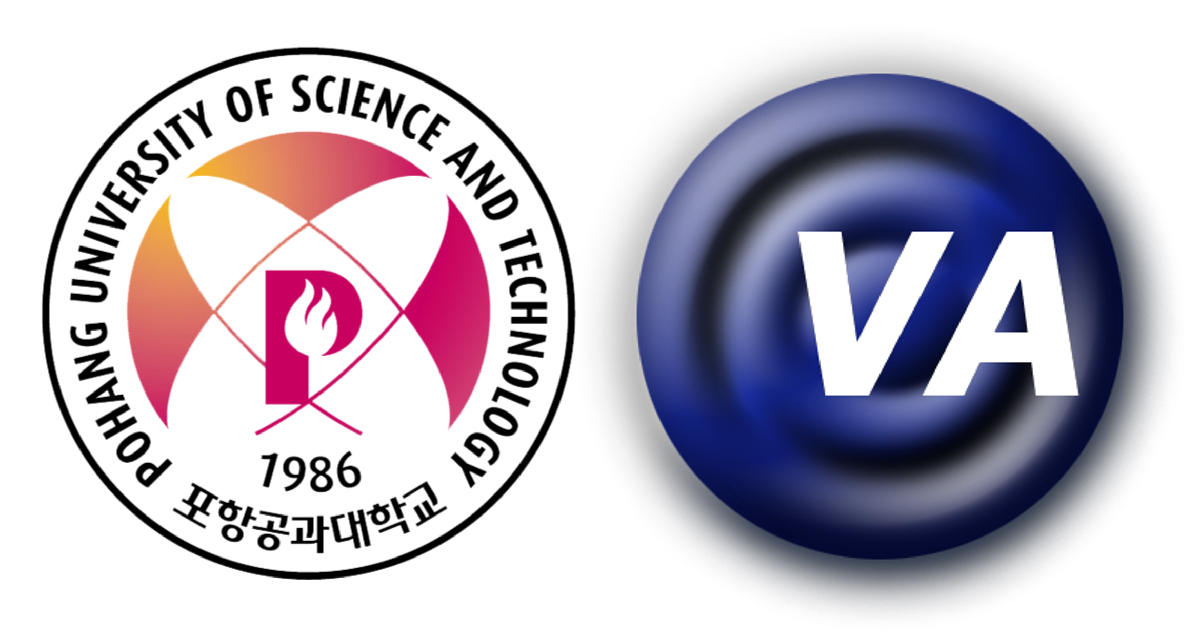

***Woongji Kim***

[wj.kim@postech.ac.kr](mailto:wj.kim@postech.ac.kr)

clear
proj = currentProject;

syms theta1 theta4

% Define the simulation frequency
f_r = 75e3;

% Load the material properties
mat = import_material('materials_OBS_loss.txt');

% Initialize the symbols for material properties and design parameters of elements
r1 = 7e-3;
r2 = 7e-3;
r3 = 7e-3;
% r4 = 1e-3;
% r4 = [0.5e-3 1e-3 1.5e-3 3.5e-3];
r4 = [0.5e-3:0.05e-3:1e-3 1.1e-3:0.1e-3:2e-3 2.25e-3:0.25e-3:5e-3];

Z1 = @(r1) mat("Stainless Steel",:).rho *mat("Stainless Steel",:).v3    *pi*r1^2;
Z2 = @(r2) mat("C-21",:).rho            *mat("C-21",:).v3               *pi*r2^2;
Z3 = @(r3) mat("Aluminum",:).rho        *mat("Aluminum",:).v3           *pi*r3^2;
Z4 = @(r4) mat("Aluminum",:).rho        *mat("Aluminum",:).v3           *pi*r4^2;

c1 = mat("Stainless Steel",:).v3;
c2 = mat("C-21",:).v3;
c3 = mat("Aluminum",:).v3;
c4 = mat("Aluminum",:).v3;

theta = @(l,c) 2*pi*f_r/c*l;

l21 = 2e-3; % node position is at the center of piezoelectric material
% l21 = linspace(1e-3,3e-3,3);
l22 = 4e-3-l21;
% l3 = 2e-3;
l3 = linspace(1e-3,20e-3,191);

r4Count = length(r4);
l21Count = length(l21);
l3Count = length(l3);

[L21,L3] = meshgrid(l21,l3);
L21 = reshape(L21,[],1);
L22 = 4e-3-L21;
L3 = reshape(L3,[],1);
L0 = zeros(length(L21),1);

param = permute(repmat([L0 L21 L22 L3 L0 L0 L0],[1 1 r4Count]),[3 1 2]);
clear L1 L21 L22 L3 L4

l1 = zeros(length(l21),length(l3));
l4 = zeros(length(l21),length(l3));

for i = 1:r4Count
    for j = 1:l21Count
        tic
        for k = 1:l3Count
            % LHS of node
            eqn1 = Z1(r1)/Z2(r2)*tan(theta(l21(j),c2))*tan(theta1) == 1;
            theta1_ = double(vpasolve(eqn1,theta1,[0 pi/2]));
            if(isempty(theta1_))
                param(i,(j-1)*l3Count+k,1) = c1/(4*f_r);
            else
                param(i,(j-1)*l3Count+k,1) = theta1_*c1/(2*pi*f_r);
            end

            % RHS of node
            eqn2 = Z3(r3)/Z2(r2)*tan(theta(l22(j),c2))*tan(theta(l3(k),c3))...
                + Z4(r4(i))/Z3(r3)*tan(theta(l3(k),c3))*tan(theta4)...
                + Z4(r4(i))/Z2(r2)*tan(theta4)*tan(theta(l22(j),c2)) == 1;
            theta4_ = double(vpasolve(eqn2,theta4,[0 pi/2]));
            if(isempty(theta4_))
                param(i,(j-1)*l3Count+k,5) = 0;
            else
                param(i,(j-1)*l3Count+k,5) = theta4_*c4/(2*pi*f_r);
            end
        end
        toc
    end
    % LHS validation
    eqn1Chk = @(l1, l2)...
        Z1(r1)/Z2(r2).*tan(theta(l2,c2)).*tan(theta(l1,c1));
    param(i,:,6) = eqn1Chk(param(i,:,1),param(i,:,2));
    paramChkidx1 = find(param(i,:,6)<=0.99 | param(i,:,6)>=1.01);
    param(i,paramChkidx1,:) = permute(repmat([0 0 0 0 0 0 0],[1 1 length(paramChkidx1)]),[1 3 2]);

    % RHS valiadation
    eqn2Chk = @(l2, l3, l4)...
        Z3(r3)/Z2(r2).*tan(theta(l2,c2)).*tan(theta(l3,c3)) + ...
        Z4(r4(i))/Z3(r3).*tan(theta(l3,c3)).*tan(theta(l4,c4)) + ...
        Z4(r4(i))/Z2(r2).*tan(theta(l4,c4)).*tan(theta(l2,c2));
    param(i,:,7) = eqn2Chk(param(i,:,3),param(i,:,4),param(i,:,5));
    paramChkidx2 = find(param(i,:,7)<=0.99 | param(i,:,7)>=1.01);
    param(i,paramChkidx2,:) = permute(repmat([0 0 0 0 0 0 0],[1 1 length(paramChkidx2)]),[1 3 2]);
end

f = 1e3:10:140e3;
fCount = length(f);
uGlobal = zeros(r4Count, l21Count, l3Count, fCount, 5);

% Import the material properties
mat = import_material('materials_OBS_loss.txt');
e_  = [1; 2; 3; 4];
l   = [0; 0; 0; 0];
r   = [0; 0; 0; 0];
A   = [0; 0; 0; 0];
Mat = ["Stainless Steel"; "C-21"; "Aluminum"; "Aluminum"];
piezoCount  = [1; 4; 1; 1];

paramECM = table(e_, l, r, A, Mat, piezoCount);
clear e_ l r A Mat piezoCount

for i = 1:r4Count
    for j = 1:l21Count
        for k = 1:l3Count
            tic
            % Define the parameters for ECM
            e_  = [1; 2; 3; 4];
            l   = [0; 0; 0; 0];
            r   = [0; 0; 0; 0];
            A   = [0; 0; 0; 0];
            Mat = ["Stainless Steel"; "C-21"; "Aluminum"; "Aluminum"];
            piezoCount  = [1; 4; 1; 1];
            
            paramECM = table(e_, l, r, A, Mat, piezoCount);
            clear e_ l r A Mat piezoCount

            nStart  = 1;
            nEnd    = 5;
            nCount  = nEnd - nStart+1;
            eCount  = nCount - 1;
            ePiezo  = 2;
    
            paramECM.r(1) = r1;
            paramECM.r(2) = r2;
            paramECM.r(3) = r3;
            paramECM.r(4) = r4(i);
    
            paramECM.A = pi*(paramECM.r).^2;
    
            paramECM.l(1) = squeeze(param(i,(j-1)*l3Count+k,1));
            paramECM.l(2) = squeeze(param(i,(j-1)*l3Count+k,2)) + squeeze(param(i,(j-1)*l3Count+k,3));
            paramECM.l(3) = squeeze(param(i,(j-1)*l3Count+k,4));
            paramECM.l(4) = squeeze(param(i,(j-1)*l3Count+k,5));

            if paramECM.l(1) == 0
                continue
            end
    
            % Initialize the symbols for material properties and design parameters of elements
            paramECM = sortrows(innerjoin(paramECM, mat));
    
            % Calculating the bar's impedance for symmetric T-network
            Z_b = zeros(fCount, nCount);  % Z_b
            Z_c = zeros(fCount, nCount);  % Z_c = Z_a + Z_b
            Z_d = zeros(fCount, nCount);  % Z_d for the boundary conditions of both ends
    
            for l = 1:eCount
                Z_b(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l)*(1+1i/paramECM.Q(l)))*paramECM.A(l)./(sin(2*pi*f./(paramECM.v3(l)*(1+1i/paramECM.Q(l))).*paramECM.l(l)));
                Z_c(:,l) = -1j*paramECM.rho(l)*(paramECM.v3(l)*(1+1i/paramECM.Q(l)))*paramECM.A(l).*cot(2*pi*f./(paramECM.v3(l)*(1+1i/paramECM.Q(l))).*paramECM.l(l));
            end
    
            % Initialize the symbols for effort and flow variable vectors
            F   = zeros(fCount, nCount);
            u   = zeros(fCount, nCount);
            V   = 10;
    
            % Define the bounrady conditions of both ends
            Z_d(:,1) = 0;
            Z_d(:,nCount) = 0;
    
            % Constructing the impedance matrix
            Z = zeros(fCount,nCount,nCount);
            
            Z(:,1,1)        = Z_c(:,1) + Z_d(:,1);
            Z(:,1,2)        = -Z_b(:,1);
            Z(:,1,3:nCount) = 0;
    
            for l=2:nCount-1
                Z(:,l,1:l-2)  = 0;
                Z(:,l,l-1)    = -Z_b(:,l-1);
                Z(:,l,l)      = Z_c(:,l-1) + Z_c(:,l);
                Z(:,l,l+1)    = -Z_b(:,l);
                Z(:,l,l+2:nCount)= 0;
            end
            
            Z(:,nCount, 1:nCount-2) = 0;
            Z(:,nCount, nCount-1)   = -Z_b(:,nCount-1);
            Z(:,nCount, nCount)     = Z_c(:,nCount-1) + Z_d(:,nCount);
    
            N = paramECM.A(ePiezo)*paramECM.d33(ePiezo)*paramECM.piezoCount(ePiezo)/paramECM.l(ePiezo)*paramECM.Y33(ePiezo);
            F(:,ePiezo) = N*V;
            F(:,ePiezo+1) = -N*V;
    
            for l=1:fCount
                u(l,1:nCount) = squeeze(Z(l,1:nCount,1:nCount))\F(l,1:nCount)';
            end
            uGlobal(i,j,k,:,:) = u;
            toc
        end
    end
end

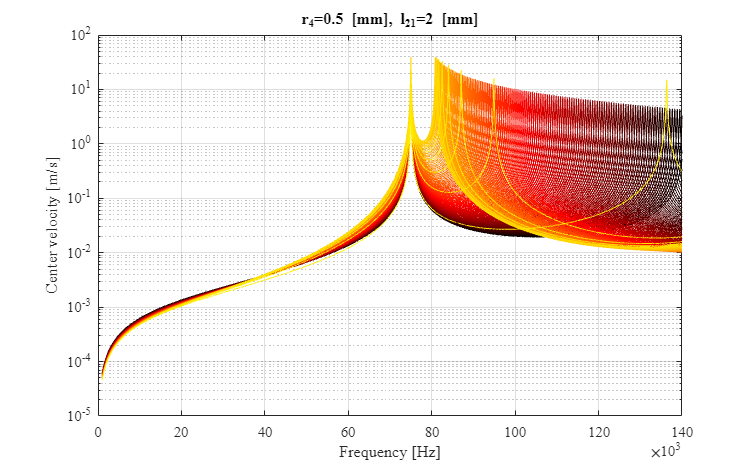

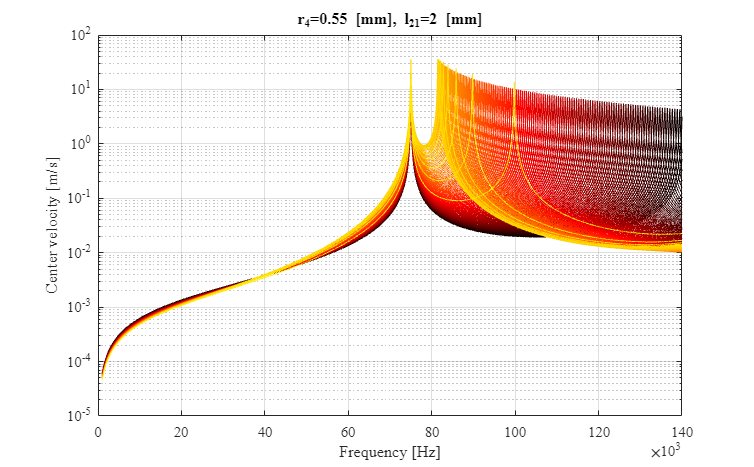

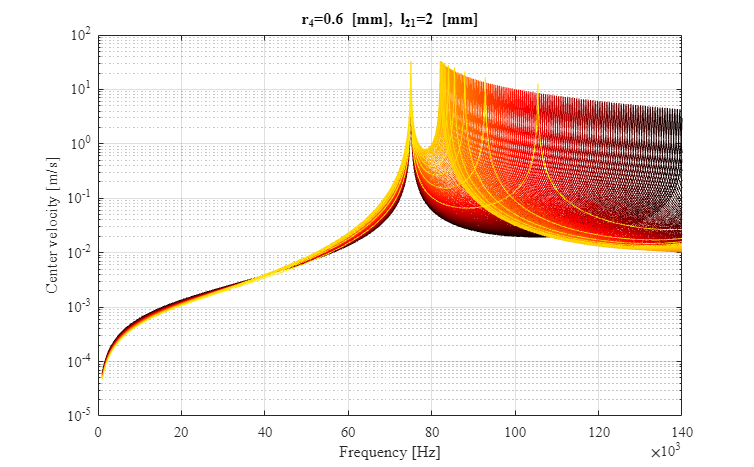

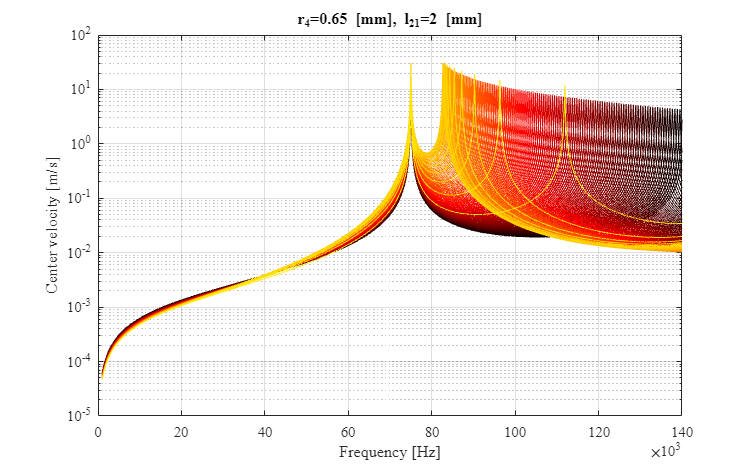

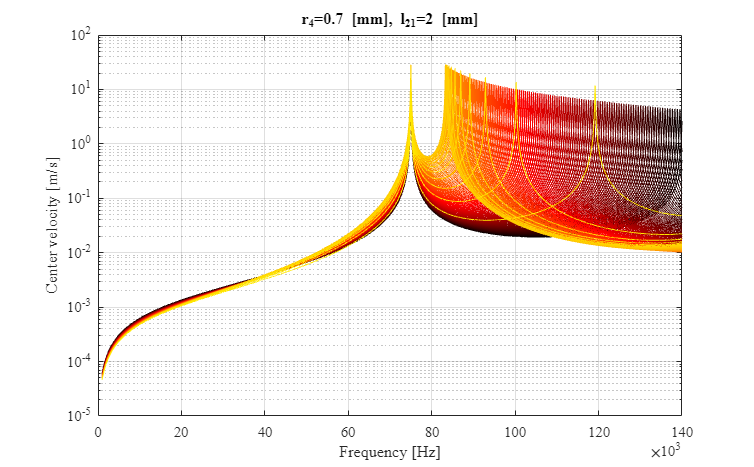

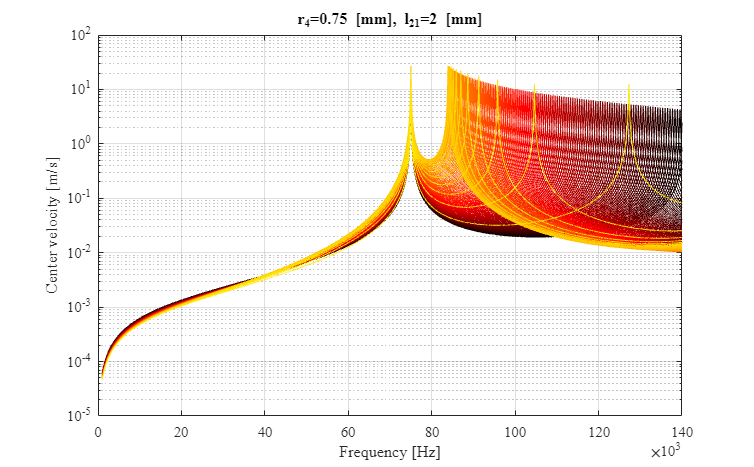

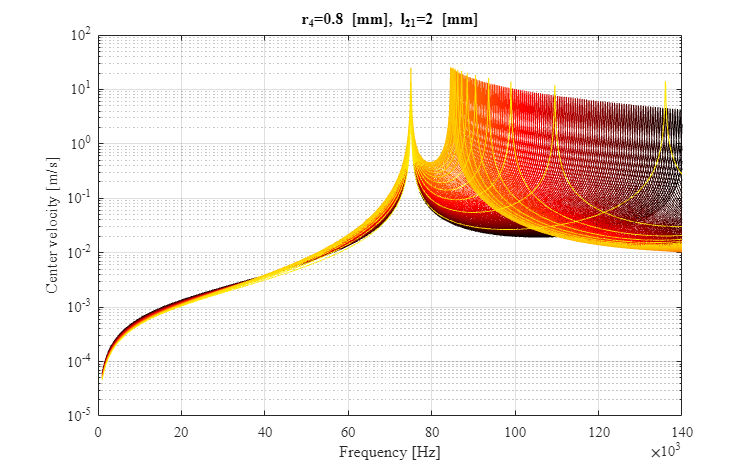

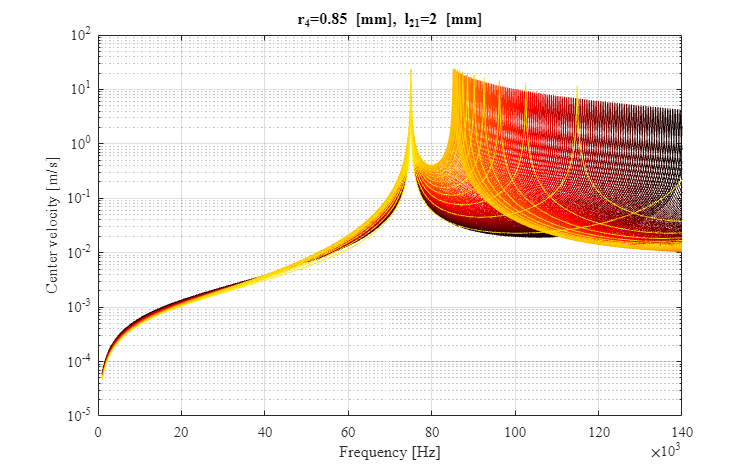

for i = 1:r4Count
    for j = 1:l21Count
        createfigure_fr_vrfe(f,abs(squeeze(uGlobal(i,j,:,:,5))),r4(i),l21(j))
    end
end

f75idx = find(f==f_r);
uGlobal75 = squeeze(uGlobal(:,:,:,f75idx,:));

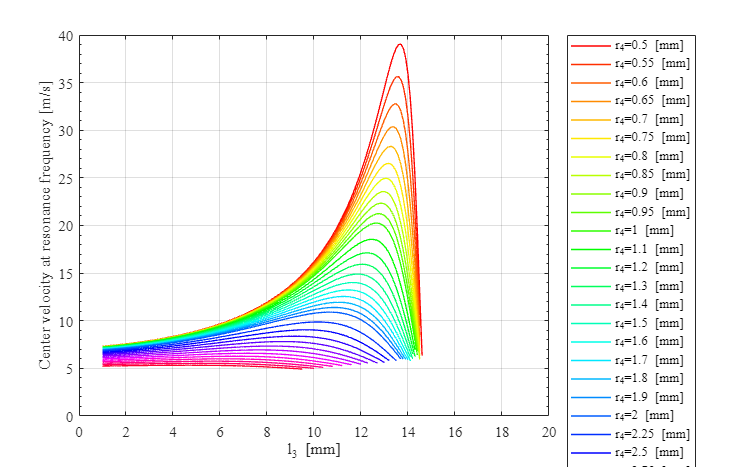

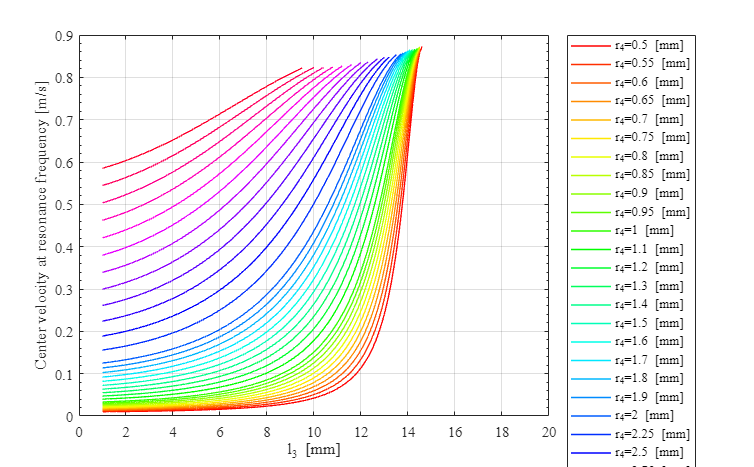

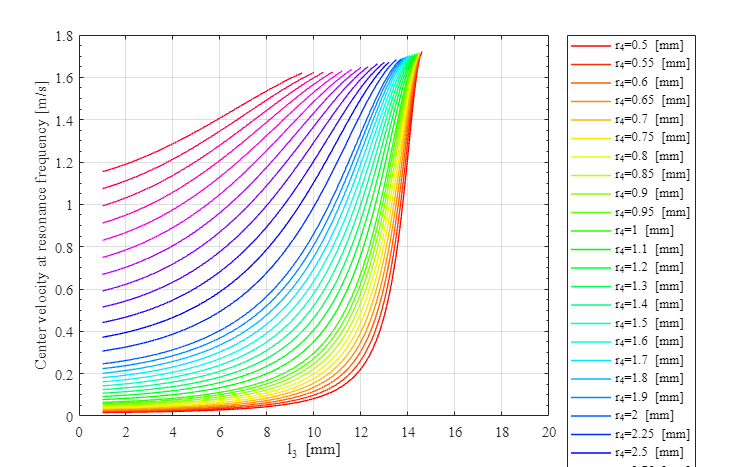

if l21Count == 1
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,5))),r4,l21)
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,3))),r4,l21)
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,1))),r4,l21)
else
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,:,5))),r4,l21)
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,:,3))),r4,l21)
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,:,1))),r4,l21)
end

if l21Count == 1
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,5)./uGlobal75(:,:,3))),r4,l21)
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,5)./uGlobal75(:,:,1))),r4,l21)
else
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,:,5)./uGlobal75(:,:,:,3))),r4,l21)
    createfigure_l3v_vrfe(l3,squeeze(abs(uGlobal75(:,:,:,5)./uGlobal75(:,:,:,1))),r4,l21)
end

if l21Count == 1
    for i = 1:r4Count
        createfigure_l3vr_vrfe(l3,squeeze(uGlobal75(i,:,:)),Z1(r1),Z4(r4(i)),r2,r4(i),l21(j))
    end
else
    for i = 1:r4Count
        for j = 1:l21Count
            createfigure_l3vr_vrfe(l3,squeeze(uGlobal75(i,j,:,:)),Z1(r1),Z4(r4(i)),r2,r4(i),l21(j))
        end
    end
end

% max peak for each radius
if l21Count == 1
    for i = 1:r4Count
        [u5(i), locPeak(i)] = findpeaks(squeeze(abs(uGlobal75(i,:,5))));
        u3(i) = squeeze(abs(uGlobal75(i,locPeak(i),3)));
        u1(i) = squeeze(abs(uGlobal75(i,locPeak(i),1)));
        u53Ratio(i) = squeeze(abs(uGlobal75(i,locPeak(i),5)./uGlobal75(i,locPeak(i),3)));
        u51Ratio(i) = squeeze(abs(uGlobal75(i,locPeak(i),5)./uGlobal75(i,locPeak(i),1)));
        aRatio(i) = r2^2/r4(i)^2;
        zRatio(i) = Z1(r1)/Z4(r4(i));
    end
    createfigure_r4vr_vrfe(r4, [u5; u3; u1; u53Ratio; u51Ratio; aRatio; zRatio]);
else
    for i = 1:r4Count
        for j = 1:l21Count
            [u5(i,j), locPeak(i,j)] = findpeaks(squeeze(abs(uGlobal75(i,j,:,5))));
            u53Ratio(i,j) = squeeze(abs(uGlobal75(i,j,locPeak(i,j),5)./uGlobal75(i,j,locPeak(i,j),3)));
            u51Ratio(i,j) = squeeze(abs(uGlobal75(i,j,locPeak(i,j),5)./uGlobal75(i,j,locPeak(i,j),1)));
            aRatio(i,j) = r2^2/r4(i)^2;
            zRatio(i,j) = Z1(r1)/Z4(r4(i));
        end
    end
    % for various l21, plot later
    [l21_,r4_] = meshgrid(l21,r4);
    contourf(r4_, l21_, u5)
end

% for various l21, plot later
for i=1:10:l3Count
    createfigure_ratio_vrfe(r4,squeeze(uGlobal75(:,i,:)),aRatio,zRatio,l3(i));
end

addpath('D:\wj\OneDrive - postech.ac.kr\0 - Doctoral research\D -230612 - Validation of resonant frequency equation')
model = mphopen('D -230612 - Validation of resonant frequency equation')
model.hist.disable;
uGlobalFEM = zeros(r4Count, l21Count, l3Count, 6);
waitBar = waitbar(0,'1','Name','Calculating in COMSOL Multiphyiscs...',...
    'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
setappdata(waitBar,'canceling',0);

r4FEM = [1:5:21 23:2:33];
r4CountFEM = length(r4FEM);
l21FEM = 1;
l21CountFEM = length(l21FEM);
l3FEM = 1:10:191;
l3CountFEM = length(l3FEM);

itertotalFEM = r4CountFEM*l21CountFEM*l3CountFEM;
for i = r4FEM
    for j = l21FEM
        for k = l3FEM
% for i = 1
%     for j = 1
%         for k = 1:2
            tic
            % Check for clicked Cancel button
            if getappdata(waitBar,'canceling')
                break
            end

            % Define the parameters for FEM
            if l1 == 0
                continue
            end
            
            % Eigenfrequency w.o. Plate/Solution 1/dset1/std1
            model.param.set('r4',[num2str(r4(i)*1e3) ' [mm]']);
            model.param.set('l1',[num2str(squeeze(param(i,(j-1)*l3Count+k,1))*1e3) ' [mm]']);
            model.param.set('l3',[num2str(squeeze(param(i,(j-1)*l3Count+k,4))*1e3) ' [mm]']);
            model.param.set('l4',[num2str(squeeze(param(i,(j-1)*l3Count+k,5))*1e3) ' [mm]']);
            
            mphrun(model,'std1');

            freq_1 = mphglobal(model,'freq','dataset','dset1');
            freq_1_idx = find(abs(freq_1)>70e3 & abs(freq_1)<80e3);

            % Frequency Domain w.o. Plate/Solution 4/dset3/std2
            model.study('std2').feature('freq').set('plist', num2str(ceil(abs(freq_1(freq_1_idx)))));
            
            mphrun(model,'std2');

            freq_2 = mphglobal(model,'freq','dataset','dset3');

            uGlobalFEM(i,j,k,1) = freq_2;
            uGlobalFEM(i,j,k,2) = mphevalpoint(model,'abs(solid.u_tZ)','selection',1,'dataset','dset3');
            uGlobalFEM(i,j,k,3) = mphevalpoint(model,'abs(solid.u_tZ)','selection',6,'dataset','dset3');
            uGlobalFEM(i,j,k,4) = mphevalpoint(model,'abs(solid.u_tZ)','selection',8,'dataset','dset3');

            mphplot(model,'pg10');
            saveas(gcf,['results\L_vp_r4=',num2str(r4(i)*1e3,'%02.3f'),'_l3=',num2str(l3(k)*1e3,'%02.3f'),'.svg'],'svg')
            close(gcf)

            % Eigenfrequency w. Plate/Solution 7/dset7/std4
            mphrun(model,'std4');

            freq_3 = mphglobal(model,'freq','dataset','dset7');
            freq_3_idx = find(abs(freq_3)>70e3 & abs(freq_3)<80e3);

            % Frequency Domain w. Plate/Solution 6/dset5/std3
            model.study('std3').feature('freq').set('plist', ceil(abs(freq_3(freq_3_idx))));
            
            mphrun(model,'std3');
            
            freq_4 = mphglobal(model,'freq','dataset','dset5');
            
            uGlobalFEM(i,j,k,5) = freq_4;
            uGlobalFEM(i,j,k,6) = mphevalpoint(model,'abs(solid2.u_tZ)','selection',1,'dataset','dset5');
            uGlobalFEM(i,j,k,7) = mphevalpoint(model,'abs(solid2.u_tZ)','selection',6,'dataset','dset5');
            uGlobalFEM(i,j,k,8) = mphevalpoint(model,'abs(solid2.u_tZ)','selection',9,'dataset','dset5');

            mphplot(model,'pg17');
            saveas(gcf,['results\P_vp_r4=',num2str(r4(i)*1e3,'%02.3f'),'_l3=',num2str(l3(k)*1e3,'%02.3f'),'.svg'],'svg')
            close(gcf)

            % Update waitbar and message
            iterFEM = (i-1)*l21CountFEM+(j-1)*l3CountFEM+k;
            waitbar(iterFEM/itertotalFEM,waitBar,sprintf('%d / %d',iterFEM,itertotalFEM))
            toc
        end
    end
end
delete(waitBar)